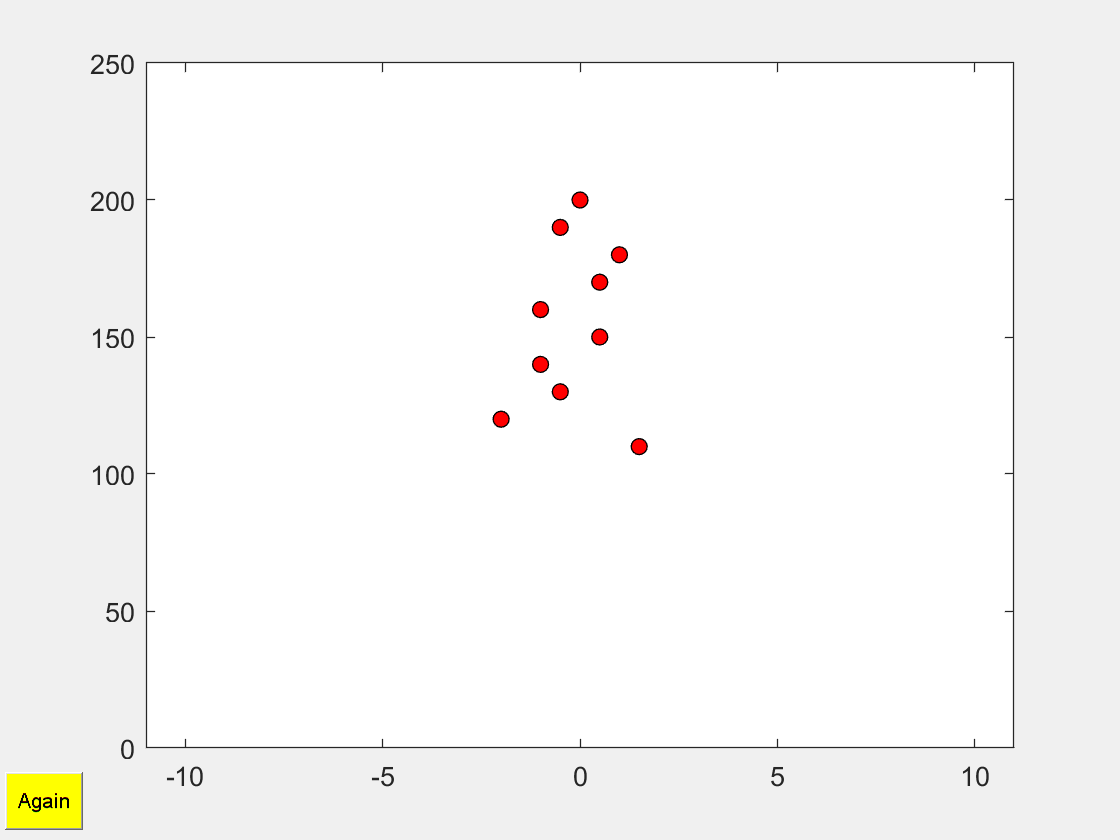

clear;
% vector of positions for balls
N = 20; % number of levels
pos = [];
offset = N/2+1;
bins = zeros(1,2*offset);

 
figure(99);clf
xvec = -offset+1:offset;
hbar = bar(xvec,bins);hold on
hballs = plot(0,N,'ko');
set(hballs,'markerfacecolor','red')
axis([-offset, offset, 0, 250]);

 
% main time stepping loop
for i = 1:10
    
    % add a ball to top of stack
    pos = [0,N; pos];
    
    % plotting
    set(hbar,'ydata',bins);
    set(hballs,'xdata',pos(:,1),'ydata',pos(:,2)*10);
    drawnow
    
    % add constant -y and random x
    [m,n]=size(pos);
    stepx = sign(randn(m,1))/2;
    stepy = -1*ones(m,1);
    pos = pos + [stepx, stepy];
    
    % check bottom of stack for zero y crossing...
    % if so, remove and record x position (an integer)
    if pos(end,2) <= 0
        xfinal = pos(end,1);
        whichbin = round(xfinal+offset);
        bins(whichbin) = bins(whichbin) + 1;
        pos(end,:) = [];
    end    
    
end

 
uicontrol('units','normalized','position',[.005 .01 .07 .07],...
    'string','Again','style','pushbutton','backgroundcolor',[1,1,0],...
    'callback','bean_machine');
set(gcf,'toolbar','figure');